clear all;

## Onset Conditions

dimension:

N=1500;
% correlation paramter:
eta=1;% 1 is symmetric
% amplitude
JAmp=1;
% Sparsity of J
Mdensity=0;
% Tot time 
tot_time=10;
% Delta t:
Dt=0.002;
% Temperature: Increase it!!!
T=5.0;
% Initialise
J=zeros(N,N);
%x=zeros(N,N_tot);
% ICs
var_ICs_X=0.01;
x(:,1)=var_ICs_X*randn(N,1);
M=sum(x(:,1).^2);
% Fix the constraint sum x^2=N for all t
x(:,1)=x(:,1)*sqrt(N)/sqrt(M);

## Generate Random Matrix:

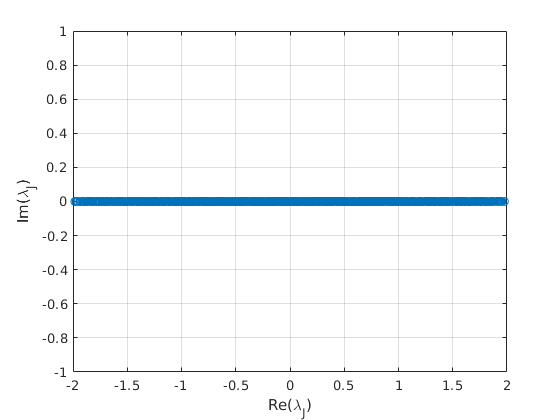

if eta==0
    J=JAmp/sqrt(N)*randn(N);   
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
J=J-diag(diag(J));
else
    a=sqrt(1-eta^2);
    a=sqrt((1-a)/2);
    b=eta/(2*a);    
    J=JAmp/sqrt(N)*randn(N);    
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
    J=a*J+b*J';
    J=J-diag(diag(J));
end;
figure;
plot(real(eig(J)),imag(eig(J)),'o');hold on;grid on;
xlabel('Re(\lambda_J)');
ylabel('Im(\lambda_J)')

%hold on;

## Run Dynamics

N_iter=tot_time/Dt;
tic
for i=2:N_iter
        z=randn(N,1)*sqrt(2*Dt*T);
        f=Dt*J*x(:,i-1)+z;
        x_norm=norm(x(:,i-1))^2;
        %x_norm=N;
        xf=x(:,i-1)'*f;
        x(:,i)=x(:,i-1)*(-xf/x_norm+sqrt((xf/x_norm)^2+(N-norm(f)^2)/x_norm))+f;
end
toc

Elapsed time is 32.051775 seconds.


x=steps(x(:,1),T,tot_time,Dt,N,J,0,10);

Elapsed time is 13.068124 seconds.


figure()
%histogram of position for one spin
bin_edge=linspace(min(x(:)),max(x(:)),50);
H=0;
for i=1:size(x,1)
    [h,b]=histcounts(x(:,i),bin_edge);
    H=H+h;
end

Index exceeds matrix dimensions.

normalisation=sum(H)*(bin_edge(2)-bin_edge(1));
plot((bin_edge(1:end-1)+bin_edge(2:end))/2,H/normalisation,'-o')
hold on
spins=(bin_edge(1:end-1)+bin_edge(2:end))/2;
prob=exp(-spins.^2/2);
plot(spins,prob/sum(prob)/(bin_edge(2)-bin_edge(1)),'-.')

I compute  $\langle x_t x_{t'}\rangle=\frac{1}{N}\sum_{i=1}^N x_{i,t}x_{i,t'}$ i.e. I average over the different realisation of the spins.

%Uldis method, is too slow
figure()
y=x(:,2001:end);
corr=0

corr =      0


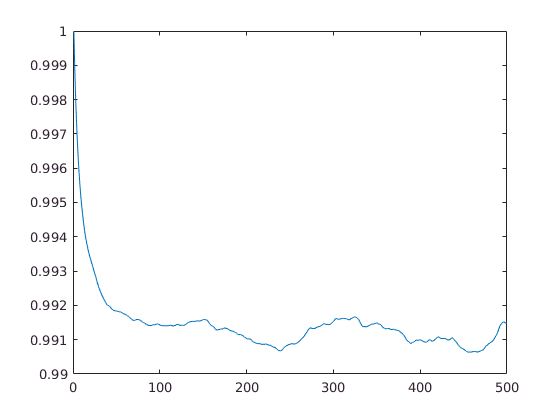

for tau=1:length(y)/2
    corr(tau)=mean(mean(y(:,tau:end).*y(:,1: end-tau+1)));
end
plot(corr)

% this is the fastest way to compute the correlation function
figure()
%t_wait=N^(2/3)/(1-T);
t_wait=0.1;
y=x(:,round(t_wait/Dt):end);% wait for thermalisation
t=round(size(y,2)/2);% this is the maximum time to observe a correlation
corr=0;
for i=1:size(y,1)
    corr=corr+xcorr(y(i,:),t,'unbiased');
end
corr=corr(ceil(end/2):end);

[mean_corr,std_corr]=correlation(x,.1,Dt,inf);

mean_corr =   Columns 1 through 769

            1      0.98995         0.98      0.97015      0.96042      0.95077      0.94122      0.93176      0.92239      0.91312      0.90393      0.89485      0.88587      0.87699      0.86821      0.85953      0.85093      0.84242      0.83399      0.82566      0.81741      0.80925      0.80117      0.79318      0.78528      0.77744       0.7697      0.76205      0.75447      0.74698      0.73957      0.73222      0.72495      0.71777      0.71066      0.70363      0.69666      0.68976      0.68294      0.67619      0.66951      0.66291      0.65637      0.64991      0.64351      0.63719      0.63093      0.62475      0.61863      0.61255      0.60654       0.6006      0.59472      0.58892      0.58317      0.57749      0.57186      0.56629      0.56078      0.55532      0.54992      0.54457      0.53928      0.53403      0.52883      0.52369      0.51861      0.51358      0.50861      0.50369      0.49881      0.49398      0.48919      0.48446 

std_corr =   Columns 1 through 769

      0.20059      0.20061      0.20063      0.20062      0.20059      0.20053      0.20046      0.20037      0.20027      0.20014      0.19998      0.19983      0.19966      0.19949       0.1993       0.1991      0.19892      0.19871       0.1985       0.1983      0.19808      0.19784       0.1976      0.19735       0.1971      0.19684      0.19657      0.19629      0.19601      0.19571       0.1954      0.19509      0.19478      0.19447      0.19415      0.19384      0.19352       0.1932      0.19288      0.19255      0.19221      0.19186      0.19151      0.19116       0.1908      0.19045       0.1901      0.18973      0.18937      0.18901      0.18863      0.18826      0.18788       0.1875      0.18712      0.18675      0.18638      0.18602      0.18565      0.18529      0.18493      0.18456      0.18419      0.18383      0.18347      0.18313       0.1828      0.18247      0.18215      0.18182      0.18149      0.18117      0.18085      0.18051  

figure()
plot((1:length(mean_corr))*Dt,mean_corr,'LineWidth',3,'DisplayName','Correlation')
xlim([0,5]);
ylim([-0.1 1.1])
hold on
%plot([0,500],[1-T,1-T],'--','LineWidth',3,'DisplayName','q=1-T')
f=fill([(1:length(mean_corr))*Dt fliplr((1:length(mean_corr))*Dt)],[mean_corr-std_corr/sqrt(N) fliplr(mean_corr+std_corr/sqrt(N))],'g','DisplayName','Std. deviation')

f =   Patch (Std. deviation) with properties:

    FaceColor: [0 1 0]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [1×4954 double]
     Vertices: [4954×2 double]

  Show all properties


set(f,'facealpha',.25)
hold off
lg=legend('show')

lg =   Legend (Correlation, Std. deviation) with properties:

         String: {'Correlation'  'Std. deviation'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.64048 0.8123 0.24107 0.082143]
          Units: 'normalized'

  Show all properties


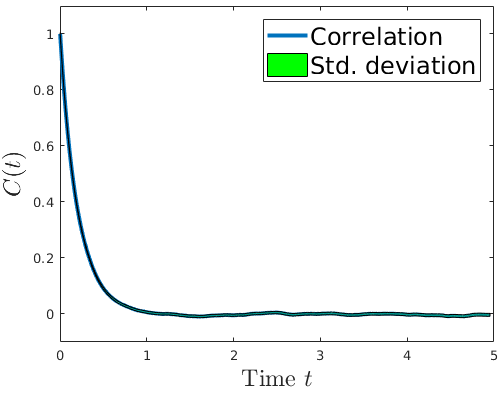

ans =   Figure (10) with properties:

      Number: 10
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [403 246 498.63 393.97]
       Units: 'pixels'

  Show all properties


lg.FontSize=18;
xlabel('Time $t$','Interpreter','latex','FontSize',18)
ylabel('$C(t)$','Interpreter','latex','FontSize',18)
tightfig()

lg =   Legend (Correlation function, 1-T) with properties:

         String: {'Correlation function'  '1-T'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 16
       Position: [0.41012 0.75992 0.47143 0.13452]
          Units: 'normalized'

  Show all properties


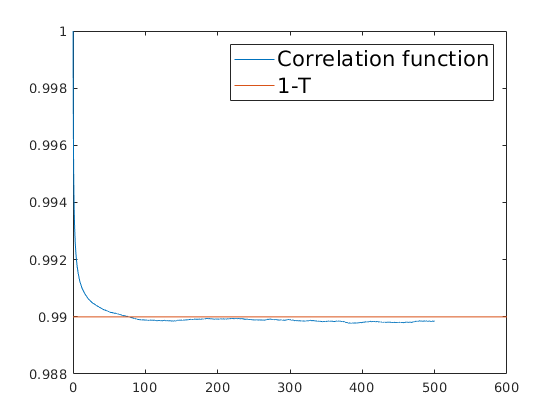

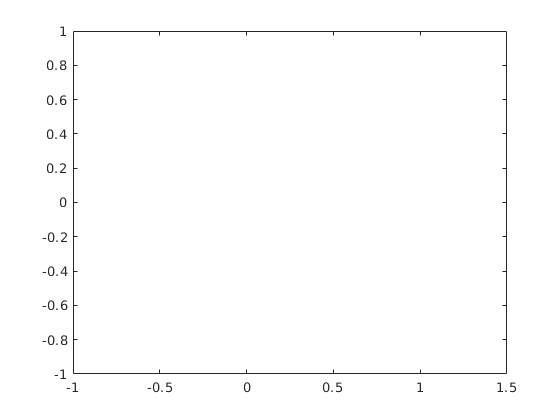

figure()
corr=0;
%hold on

for i=1:size(x,1)
    %corr=mean(x
    %corr=corr+xcorr(x(i,:),'unbiased');
end
corr=corr/N;
%hold off
figure()
plot((1:length(corr))*Dt,corr)

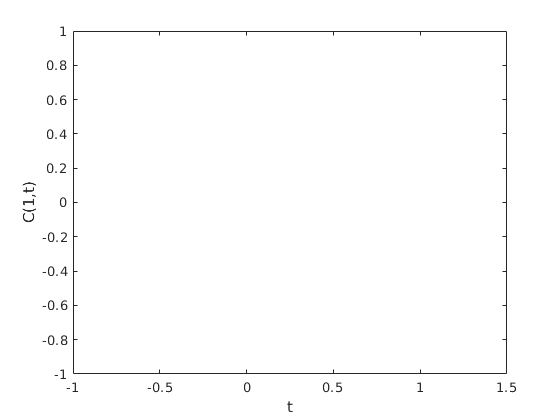

c=corr((end+1)/2:end);
plot((1:length(c))*Dt,c)
xlabel('t')
ylabel('C(1,t)')


% Fourier transfrorm of correlation function
P2=abs(fft(corr));
P1=P2(1:(end+1)/2+1);

Index exceeds matrix dimensions.

P1(2:end-1) = 2*P1(2:end-1);
f = 1/Dt*linspace(0,0.5,N_iter);
plot(f,P1(1:end-1))

